clear;clc;close all
load('orbitdeterm_finalproj_KFdata.mat')

## Define Constants

mu = 3.986004418e5; %398800; % [km^3/s^2] Gravitational Constant
r0 = 6678; % [km] nominal orbit radius
w0 = sqrt(mu/r0^3);
% Constants for the output vector
Re = 6378; % [km]
we = 2*pi/86400; % [rad/s]
N = 12; % Number of ground stationss^2
dt = 10; % [s]
dtf = 0.1; % [s] fine dt
Tf = 14000; % [s] Final time (one orbit)
G = [0 0;1 0;0 0;0 1]; % Big omega matrix
O = dt*G;

## Nominal Trajectory

t = 0:dt:Tf;
t_fine = 0:dtf:Tf;
opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
xnom(:,1) = [r0;0;0;r0*w0];
for kk = 1:length(t)-1
   f = @(t,x) nLEQ(t,x);
   [~,xnom_ODE] = ode45(f,[0 10],xnom(:,kk),opts);
   xnom(:,kk+1) = xnom_ODE(end,:)';
end


## Linear Kalman Filter

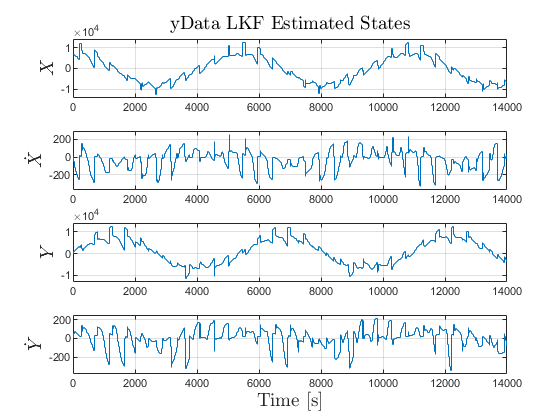

P(:,:,1) = eye(4)*1e-10;
Qassumed = [0.9 0.3;0.3 0.9];
%     Qassumed = Qtrue;
    Rassumed = Rtrue;
    Qt_diag = diag(Qassumed);
    dx(:,1) = [0; 0; 0; 0];
    dx_predict(:,1) = [0; 0.075; 0; -0.021]*0; % State prediction
    P_predict(:,:,1) = eye(4);
    for kk = 1:length(ydata)-1
        % Define matrices
        F = eye(4) + dt*A(xnom(:,kk),mu);
        H_kp1 = [];
        dy_kp1 = [];
        Rused = [];
        yin = ydata{kk+1};
        if size(yin,2) == 1
            Rused = kron(eye(1),Rassumed);
            for ii = 1:2
                H_kp1 = C(xnom(:,kk+1),t(kk+1),yin(4));
                yin(3) = wrapToPi(yin(3));
                dy_kp1 = yin(1:3);
            end
        elseif size(yin,2) == 2
            Rused = kron(eye(2),Rassumed);
            H_kp1 = [C(xnom(:,kk+1),t(kk+1),yin(4,1));
                C(xnom(:,kk+1),t(kk+1),yin(4,2))];
            yin(3,1) = wrapToPi(yin(3,1));
            yin(3,2) = wrapToPi(yin(3,2));
            dy_kp1 = [yin(1:3,1);yin(1:3,2)];
        end
        
            % Prediction Step
            dx_predict(:,kk+1) = F*dx(:,1);
            P_predict(:,:,kk+1) = F*P(:,:,kk)*F' + O*Qassumed*O';
    
    
            if ~isempty(H_kp1)
            % Measurement Update
                K = P_predict(:,:,kk+1)*H_kp1'*inv(H_kp1*P_predict(:,:,kk+1)*H_kp1'+Rused);
                dx(:,kk+1) = dx_predict(:,kk+1) + K*(dy_kp1-H_kp1*dx_predict(:,kk+1));
                P(:,:,kk+1) = (eye(4) - K*H_kp1)*P_predict(:,:,kk+1);
%                 innov(:,kk) = dy_kp1-H_kp1*dx_predict(:,kk+1);
            else
            % Just use prediction if no ground staions in view
                dx(:,kk+1) = dx_predict(:,kk+1);
                P(:,:,kk+1) = P_predict(:,:,kk+1);
%                 innov(:,kk) = [0;0;0];
            end
            
            
    end

figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(t,xnom(kk,:)+dx(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('yData LKF Estimated States','Interpreter','Latex','FontSize',14)
saveas(gca,'yDataLKFStates.png')

Extended Kalman Filter

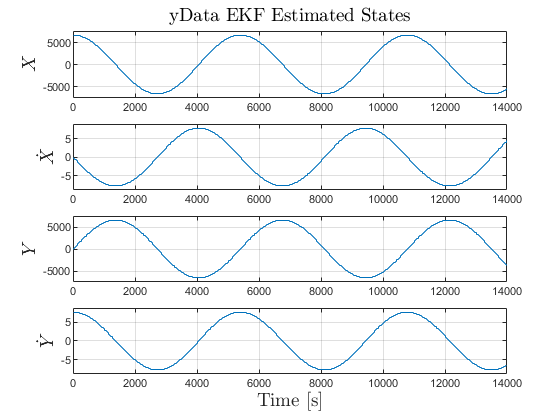

    Qassumed = [
        8e-2 2e-4;
        2e-4 8e-2]*1e-4;
    Qassumed = Qtrue;
    Rassumed = Rtrue;
    P(:,:,1) = diag([1e-4 0.0056 1e-4 4.441e-4]);
    x(:,1) = [r0;0;0;r0*w0]; % State estimate
    Qt_diag = diag(Qassumed);
    x_predict(:,1) = [0; 0.075; 0; -0.021]*0; % State prediction
    NEES(1) = 0;
    NIS(1) = 0;
    innov(:,1) = [0;0;0];
    P_predict(:,:,1) = eye(4)*100;
    for kk = 1:length(t)-1
         % Define matrices
        F = eye(4) + dt*A(xnom(:,kk),mu);
        H_kp1 = [];
        dy_kp1 = [];
        Rused = [];
        y_predict = [];
        yin = ydata{kk+1};
        if size(yin,2) == 1
            Rused = kron(eye(1),Rassumed);
            for ii = 1:2
                H_kp1 = C(xnom(:,kk+1),t(kk+1),yin(4));
                yin(3) = wrapToPi(yin(3));
                y_kp1 = yin(1:3);
            end
        elseif size(yin,2) == 2
            Rused = kron(eye(2),Rassumed);
            H_kp1 = [C(xnom(:,kk+1),t(kk+1),yin(4,1));
                C(xnom(:,kk+1),t(kk+1),yin(4,2))];
            yin(3,1) = wrapToPi(yin(3,1));
            yin(3,2) = wrapToPi(yin(3,2));
            y_kp1 = [yin(1:3,1);yin(1:3,2)];
        end

        % Prediction Step
        opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
        [~,x_ODE_Predict] = ode45(@nLEQ,[0 10],x(:,kk),opts);
       
        x_predict(:,kk+1) = x_ODE_Predict(end,:)';
        P_predict(:,:,kk+1) = F*P(:,:,kk)*F' + O*Qassumed*O';


        for ii = 1:size(yin,2)      
            % Non-linear prediction of our measurement based off of our
            % previous state estimate.
            
            thi = wrapToPi((yin(4,ii) - 1)*pi/6); % Theta 0 for ground station i
            Xis = Re*cos(we*t(kk+1)+thi);
            Yis = Re*sin(we*t(kk+1)+thi);
            dXis = -Re*we*sin(we*t(kk+1)+thi);
            dYis = Re*we*cos(we*t(kk+1)+thi);
            y_predict_single = [sqrt((x_predict(1,kk+1)-Xis)^2+(x_predict(3,kk+1)-Yis)^2);
                        ((x_predict(1,kk+1)-Xis)*(x_predict(2,kk+1)-dXis)+(x_predict(3,kk+1)-Yis)*(x_predict(4,kk+1)-dYis))/(sqrt((x_predict(1,kk+1)-Xis)^2+(x_predict(3,kk+1)-Yis)^2));
                        atan2((x_predict(3,kk+1)-Yis),(x_predict(1,kk+1)-Xis))];
            y_predict_single(3) = wrapToPi(y_predict_single(3));

            y_predict = [y_predict ; y_predict_single];

        end
        
            
    
    
            if ~isempty(H_kp1)
            % Measurement Update
                K = P_predict(:,:,kk+1)*H_kp1'*inv(H_kp1*P_predict(:,:,kk+1)*H_kp1'+Rused);
                x(:,kk+1) = x_predict(:,kk+1) + K*(y_kp1-y_predict);
                P(:,:,kk+1) = (eye(4) - K*H_kp1)*P_predict(:,:,kk+1);
            else
            % Just use prediction if no ground staions in view
                x(:,kk+1) = x_predict(:,kk+1);
                P(:,:,kk+1) = P_predict(:,:,kk+1);
            end
    end
            figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(t,x(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('yData EKF Estimated States','Interpreter','Latex','FontSize',14)
saveas(gca,'yDataEKFStates.png')